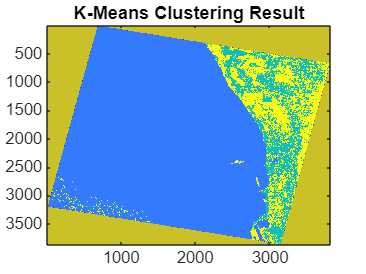

%% Clear workspace and command window
clear;
clc;

%% Data Collection
scaleFactor = 0.5;

% Load and resize Landsat 8 bands
bands = cell(1, 8);
bandFiles = {'LC08_L1TP_113082_20211206_20211206_01_RT_B1.tif', ...
              'LC08_L1TP_113082_20211206_20211206_01_RT_B2.tif', ...
              'LC08_L1TP_113082_20211206_20211206_01_RT_B3.tif', ...
              'LC08_L1TP_113082_20211206_20211206_01_RT_B4.tif', ...
              'LC08_L1TP_113082_20211206_20211206_01_RT_B5.tif', ...
              'LC08_L1TP_113082_20211206_20211206_01_RT_B6.tif', ...
              'LC08_L1TP_113082_20211206_20211206_01_RT_B7.tif', ...
              'LC08_L1TP_113082_20211206_20211206_01_RT_B9.tif'};

for i = 1:length(bandFiles)
    bands{i} = imresize(im2double(imread(bandFiles{i})), scaleFactor);
end

%% Wavelengths for Landsat 8 bands (in micrometers)
wavelengths = [0.443, 0.482, 0.561, 0.655, 0.865, 1.61, 2.2, 1.375];

%% Create Hypercube
hcube.DataCube = cat(3, bands{:});
hcube.Wavelength = wavelengths;

%% Denoising using Gaussian Filter
sigma = 1;
smoothedData = imgaussfilt3(hcube.DataCube, sigma);

%% K-Means Clustering
[numRows, numCols, numBands] = size(smoothedData);
reshapedData = reshape(smoothedData, [], numBands);

numClusters = 5;
[clusterIdx, ~] = kmeans(reshapedData, numClusters, 'MaxIter', 1000);
clusteredImage = reshape(clusterIdx, numRows, numCols);

figure;
imagesc(clusteredImage);
title('K-Means Clustering Result');

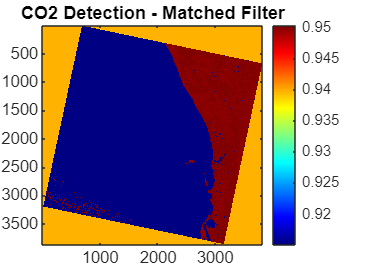

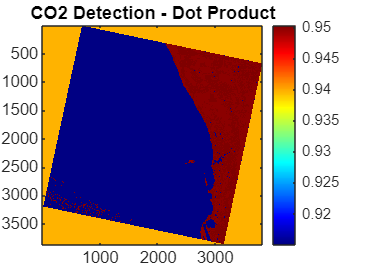

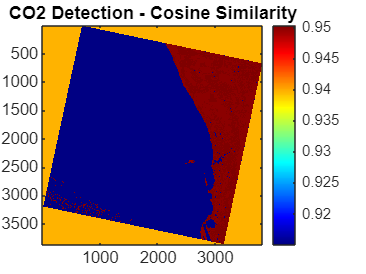


%% Custom Spectral Matching Function
function score = customSpectralMatch(spectrum, signature)
    score = dot(spectrum, signature) / (norm(spectrum) * norm(signature));
end

%% Custom Cosine Similarity Function
function score = cosineSimilarity(spectrum, signature)
    score = dot(spectrum, signature) / (norm(spectrum) * norm(signature));
end

%% Applying Spectral Matching Algorithms
co2Signature = [0.02, 0.03, 0.04, 0.05, 0.04, 0.03, 0.02, 0.01];

methods = {@customSpectralMatch, @dot, @cosineSimilarity};
methodNames = {'Matched Filter', 'Dot Product', 'Cosine Similarity'};

co2DetectionMap = zeros(numRows, numCols);

for m = 1:length(methods)
    for c = 1:numClusters
        clusterPixels = reshapedData(clusterIdx == c, :);
        meanSpectrum = mean(clusterPixels, 1);
        meanSpectrum = meanSpectrum / norm(meanSpectrum);
        co2Signature = co2Signature / norm(co2Signature);

        filterResponse = methods{m}(meanSpectrum, co2Signature);
        co2DetectionMap(clusterIdx == c) = filterResponse;
    end

    figure;
    imagesc(co2DetectionMap);
    colormap('jet');
    colorbar;
    title(['CO2 Detection - ' methodNames{m}]);
end

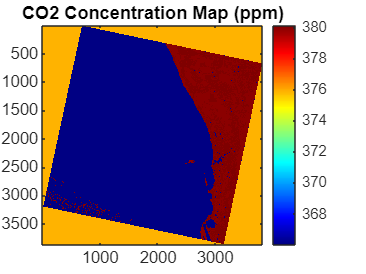


%% Visualization
scalingFactor = 400;
co2_ppm_map = co2DetectionMap * scalingFactor;
ppm_threshold = prctile(co2_ppm_map(:), 70);
co2_ppm_anomalies = co2_ppm_map > ppm_threshold;

figure;
imagesc(co2_ppm_map);
colormap('jet');
colorbar;
title('CO2 Concentration Map (ppm)');

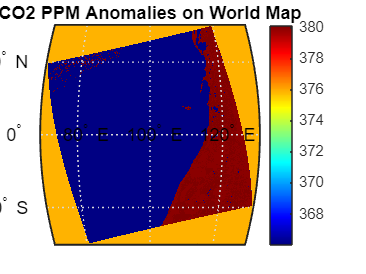


%% Mapping on World Map
minLat = -30; maxLat = 30;
minLon = 70; maxLon = 130;

lat = linspace(minLat, maxLat, numRows);
lon = linspace(minLon, maxLon, numCols);
[LON, LAT] = meshgrid(lon, lat);

figure;
worldmap([minLat, maxLat], [minLon, maxLon]);
load coastlines;
plotm(coastlat, coastlon, 'k');
geoshow(LAT, LON, double(co2_ppm_map), 'DisplayType', 'texturemap');
colormap('jet');
colorbar;
title('CO2 PPM Anomalies on World Map');